BND_st.name='BND';
BND_st.lat=40.05;
BND_st.lon=-88.37;
BND_st.alt=230;
BND_st.env='con';
BND_st.footp='RB';


BND_rd=read_betsy('BND_1994_2019N',BND_S11t.name);

datevec(BND_rd.Time(1))
datevec(BND_rd.Time(end))
prctile(BND_rd.U0_S11,[5 50 95])
prctile(BND_rd.U1_S11,[5 50 95])
prctile(BND_rd.U_S11,[5 50 95])
% figure;
% plot(BND_rd.Time, BND_rd.U0_S11,'b.');
% hold on;
% plot(BND_rd.Time, BND_rd.U1_S11,'g.');
% plot(BND_rd.Time, BND_rd.U_S11,'r.');
plotFigControl(BND_rd, BND_st.name);
% 2 size cut, ok
% sc: ok, no clear seasonal cycle, no negatives
% abs: 2 size cut, no clear seasonal cycle, few negatives
%ratio between abs wavelengths has a clear seasonal cycle with max in winter
%ratio Bs/Ba has a clear seasonality with max in winter


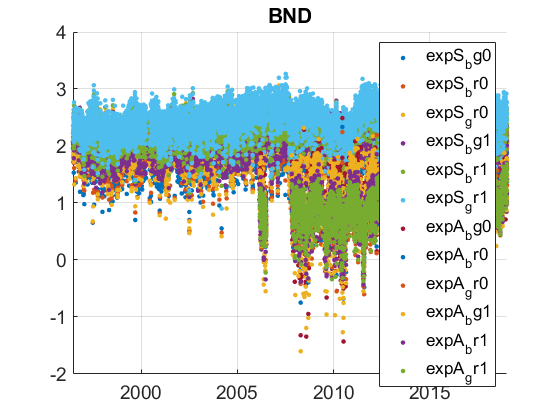

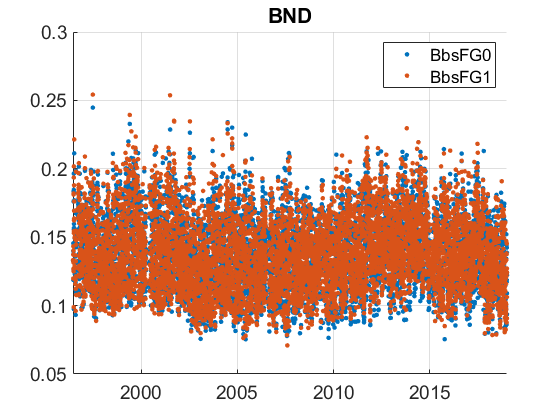

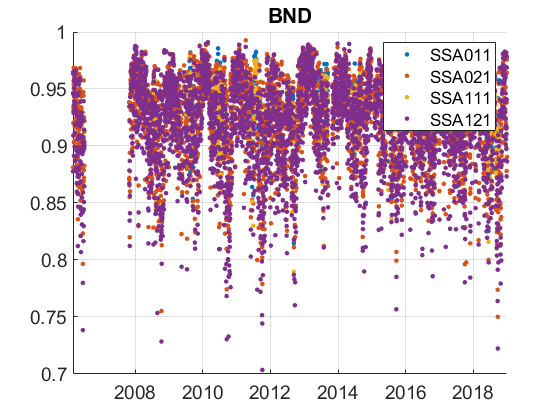

lambdaSC=[450;550;700]*ones(1,4);
lambdaAE=[467;530;660]*ones(1,4);
BND_cal=compute_exp_SSA(BND_rd,lambdaSC, lambdaAE);
plotFigControl_cal(BND_cal, BND_st.name);

%Questions:
%problems:
%sc: rupture in January 2015?
% first half of 2010: is there any problem ?
%the ratio between 2 wavelengths show problems betwwen 2011 and 2015 with a clear rupture in january 2015
% B/G increases from July 2011 until end of 2014, B/R is too high from July 2011 to end of 2014, G/R only from July 2011 to mid 2012
% expS bg: ok but exp with r are making waves (greatest on GR) !

%abs: no data in 2004 and from July 2006 to nov 2007
% ratio G/R present a clear increase during 2012-2013, any explanation? PSAP to CLAP ?
% exp A bg has a greater amplitude in 2008-2010
% exp A br low until 2011, increase until 2013 , high thereafter: real or problem ? what happens end of March 2012 ? Change from PSAP to CLAP ?
%if it is the change to CLAP it seems to affect principally the red wavelength.


%SSA has a seasonal cycle with main in winter

%N cannot be used in Jan-Mar 2008 and from feb-~mid may 1998

% break in  6 august 2011 to  15october 2012, and since 27 january 2015
%try to test mean median and var

period1=timerange('2000-01-01','2009-12-31');
period2=timerange('2011-08-06','2012-08-06');
period3=timerange('2015-01-31','2018-12-31');
TT1=BND_rd(period1,:);
TT2=BND_rd(period2,:);
TT3=BND_rd(period3,:);
BsG0_P1_mean=nanmean(TT1.BsG0_S11); BsG0_P1_median=nanmedian(TT1.BsG0_S11); BsG0_P1_var=nanvar(TT1.BsG0_S11);
BsG0_P2_mean=nanmean(TT2.BsG0_S11); BsG0_P2_median=nanmedian(TT2.BsG0_S11); BsG0_P2_var=nanvar(TT2.BsG0_S11);
BsG0_P3_mean=nanmean(TT3.BsG0_S11); BsG0_P3_median=nanmedian(TT3.BsG0_S11); BsG0_P3_var=nanvar(TT3.BsG0_S11);

%MEW DATA COMPUTE ALL AGAIN
BND_tr=BND_rd;
BND_tr.y=year(BND_tr.Time);
% begin at the beginning of a year: 1995 -2018
P=timerange('1995-01-01','2019-01-01');
BND_tr=BND_tr(P,:);

names=fieldnames(BND_tr);
c= startsWith(names,["T1";"T0";"T_";"P_";"P1_";"P0_";"N";"Uu";"U1"]) ;
N=names(c);
for i=1:length(N)
    BND_tr.(N{i})=[];
end

%only one time serie for RH, fracgmentation issue
BND_tr.U0_S11=sum([BND_tr.U_S11 BND_tr.U0_S11],2,'omitnan');
indz=BND_tr.U0_S11==0;
BND_tr.U0_S11(indz)=NaN;
BND_tr.U_S11=[];

%scat PM10/PM1 B and R: begin 1997-2018
%BbsF: 1997-2018
P2=timerange('1995-01-01','1997-01-01');
BND_tr.BsB0_S11(P2)=NaN;
BND_tr.BsR0_S11(P2)=NaN;
BND_tr.BsB1_S11(P2)=NaN;
BND_tr.BsR1_S11(P2)=NaN;
BND_tr.BbsB0_S11(P2)=NaN;
BND_tr.BbsR0_S11(P2)=NaN;
BND_tr.BbsB1_S11(P2)=NaN;
BND_tr.BbsR1_S11(P2)=NaN;
BND_tr.BsB0_S11_dry(P2)=NaN;
BND_tr.BsR0_S11_dry(P2)=NaN;
BND_tr.BsB1_S11_dry(P2)=NaN;
BND_tr.BsR1_S11_dry(P2)=NaN;
BND_tr.BbsB0_S11_dry(P2)=NaN;
BND_tr.BbsR0_S11_dry(P2)=NaN;
BND_tr.BbsB1_S11_dry(P2)=NaN;
BND_tr.BbsR1_S11_dry(P2)=NaN;

BND_tr.BbsG1_S11(P2)=NaN;
BND_tr.BbsG0_S11(P2)=NaN;
BND_tr.BsG1_S11_dry(P2)=NaN;
BND_tr.BsG0_S11_dry(P2)=NaN;
%abs: 1997 to invalidate ? oct 2002 - end 2003 to invalidate ? --> 1997 or 1998-2018
P4=timerange('1995-01-01','1998-01-01');
BND_tr.BaG0_A11(P4)=NaN;
BND_tr.BaG1_A11(P4)=NaN;

P5=timerange('2002-10-03','2004-01-01');
BND_tr.BaG0_A11(P4)=NaN;
BND_tr.BaG1_A11(P4)=NaN;
%ExpA: only since 2008
P3=timerange('1995-01-01','2008-01-01');
BND_tr.BaB0_A11(P3)=NaN;
BND_tr.BaR0_A11(P3)=NaN;
BND_tr.BaB1_A11(P3)=NaN;
BND_tr.BaR1_A11(P3)=NaN;


BND_cal2=compute_exp_SSA(BND_tr,lambdaSC, lambdaAE);

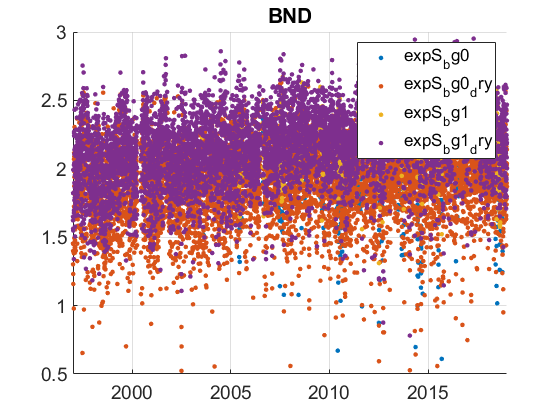

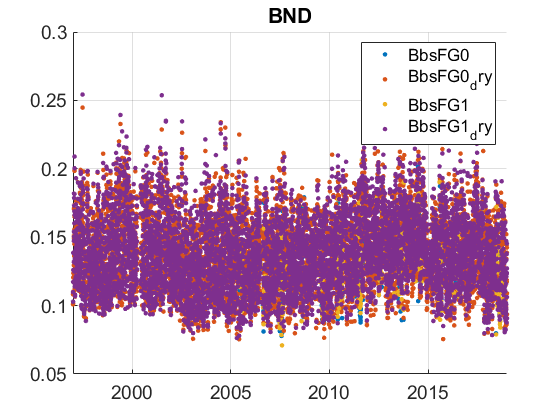

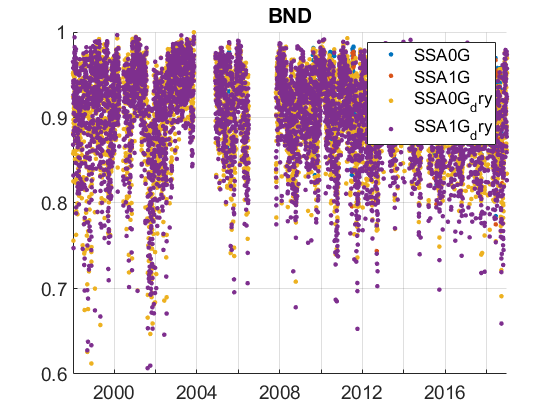

BND_cal2=timetable(BND_tr.Time);
%compute SSA with green
BND_cal2.SSA0G=BND_tr.BsG0_S11./(BND_tr.BsG0_S11+BND_tr.BaG0_A11);
BND_cal2.SSA1G=BND_tr.BsG1_S11./(BND_tr.BsG1_S11+BND_tr.BaG1_A11);
BND_cal2.SSA0G_dry=BND_tr.BsG0_S11_dry./(BND_tr.BsG0_S11_dry+BND_tr.BaG0_A11);
BND_cal2.SSA1G_dry=BND_tr.BsG1_S11_dry./(BND_tr.BsG1_S11_dry+BND_tr.BaG1_A11);

BND_cal2.BbsFG0=BND_tr.BbsG0_S11./BND_tr.BsG0_S11;
BND_cal2.BbsFG0_dry=BND_tr.BbsG0_S11_dry./BND_tr.BsG0_S11_dry;
BND_cal2.BbsFG1=BND_tr.BbsG1_S11./BND_tr.BsG1_S11;
BND_cal2.BbsFG1_dry=BND_tr.BbsG1_S11_dry./BND_tr.BsG1_S11_dry;

BND_cal2.expS_bg0=real(-log(BND_tr.BsB0_S11./BND_tr.BsG0_S11)/log(lambdaSC(1)/lambdaSC(2)));
BND_cal2.expS_bg0_dry=real(-log(BND_tr.BsB0_S11_dry./BND_tr.BsG0_S11_dry)/log(lambdaSC(1)/lambdaSC(2)));
BND_cal2.expS_bg1=real(-log(BND_tr.BsB1_S11./BND_tr.BsG1_S11)/log(lambdaSC(1)/lambdaSC(2)));
BND_cal2.expS_bg1_dry=real(-log(BND_tr.BsB1_S11_dry./BND_tr.BsG1_S11_dry)/log(lambdaSC(1)/lambdaSC(2)));

plotFigControl_cal(BND_cal2, BND_st.name);

BND_tr=outerjoin(BND_tr, BND_cal2);

%compute trend only on green
BND_tr.BsB0_S11=[];
BND_tr.BsB0_S11_dry=[];
BND_tr.BsR0_S11=[];
BND_tr.BsR0_S11_dry=[];
BND_tr.BbsB0_S11=[];
BND_tr.BbsB0_S11_dry=[];
BND_tr.BbsR0_S11=[];
BND_tr.BbsR0_S11_dry=[];

BND_tr.BsB1_S11=[];
BND_tr.BsB1_S11_dry=[];
BND_tr.BsR1_S11=[];
BND_tr.BsR1_S11_dry=[];
BND_tr.BbsB1_S11=[];
BND_tr.BbsB1_S11_dry=[];
BND_tr.BbsR1_S11=[];
BND_tr.BbsR1_S11_dry=[];

BND_tr.BaB0_A11=[];
BND_tr.BaB1_A11=[];
BND_tr.BaR0_A11=[];
BND_tr.BaR1_A11=[];



%expA BG: change higher minima since the PSAP-CLAP change on 25th March 2012


BND_result= all_trend_STN(BND_tr,BND_st); 
plot_10y_in_two(BND_result, BND_st);

BND_result_D=BND_result;